clear all;
close all;

Lx = 1; % Longueur x
Ly = 1; % Longueur y
r = 0.001; % Rayon des charges
kc = 20; % Conductivité charges
ki = 1; % Conductivité isolant
Nx = 512; % Nb de points x
Ny = 512; % Nb de points y

fstart = 0.05; % f de départ
fend = 1; % f final
df = 0.05; % pas
Nb = 10; % Nb de simulations pour une valeur de fs
Ncores = maxNumCompThreads() - 1 % Nb threads disponibles

Ncores = 3


f_list = fstart:df:fend;
num_steps = length(f_list);

lambdaEq = zeros(num_steps, 1);
Favg = zeros(num_steps, 1);

if isempty(gcp('nocreate'))
    parpool('local', Ncores);
end

for i = 1:num_steps
    fs = f_list(i);
    fprintf("Start fs = %.0f\n", int16(fs*100))

    lambda = zeros(Nb, 1);
    F = zeros(Nb, 1);

    parfor j=1:Nb
        [F(j), lambda(j)] = Reso1Cas2D(Lx, Ly, r, fs, kc, ki, Nx, Ny);
    end

    lambdaEq(i) = mean(lambda);
    Favg(i) = mean(F);
end

Start fs = 5
Start fs = 10
Start fs = 15
Start fs = 20
Start fs = 25
Start fs = 30
Start fs = 35
Start fs = 40
Start fs = 45
Start fs = 50
Start fs = 55
Start fs = 60
Start fs = 65
Start fs = 70
Start fs = 75
Start fs = 80
Start fs = 85
Start fs = 90
Start fs = 95
Start fs = 100


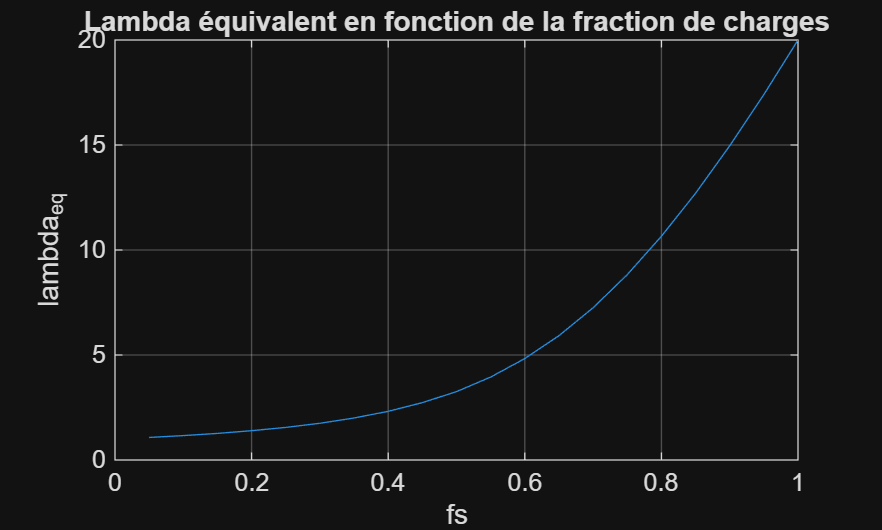


plot(Favg, lambdaEq)
xlabel("fs")
ylabel("lambda_{eq}")
grid on
title("Lambda équivalent en fonction de la fraction de charges")